lambda_pla = 0.13;
lambda_luft = 25.50 * 10^-3;
M_vand = 997;
c_vand = 4187;

l_pla = 5 * 10^-3;
l_luft = 10 * 10^-3;
H_tank = 0.1;
B_tank = 0.1;
L_tank = 0.1;
T_luft = 21;

V_tank = H_tank * B_tank * L_tank;
A_tank = H_tank * B_tank * 2 + B_tank * L_tank * 2 + L_tank * H_tank * 2;

U_pla = lambda_pla / l_pla;
U_luft = lambda_luft / l_luft;
U_tot = 1/((1/U_pla)+(1/U_luft)+(1/U_pla));

m_dej = V_tank * M_vand;
Q_dej = c_vand * m_dej;
T_dej = T_luft, zeros(1, 2*10800 - 1);

T_dej = 21

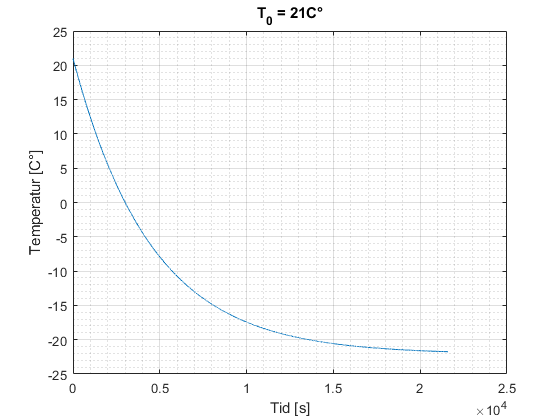


for s = 2:2*10800
    phi_tab = U_tot * A_tank * (T_luft - T_dej(s-1));
    phi_peltier = 40 - 0.8*(T_luft - T_dej (s-1));
    phi_tot = phi_peltier - phi_tab;
    T_dej(s) = T_dej(s-1) - phi_tot / Q_dej;
end
%%
plot(T_dej);
title("T_0 = 21C°")
xlabel("Tid [s]")
ylabel("Temperatur [C°]")
grid on; grid minor

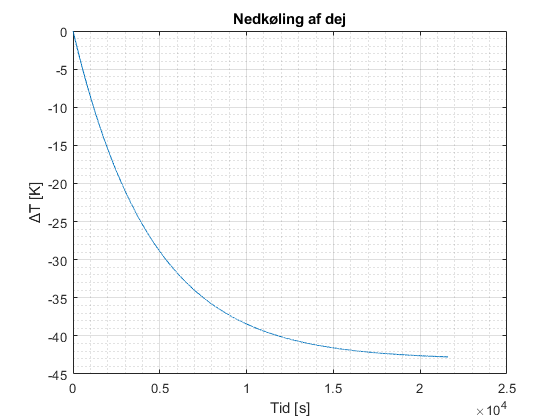

T_delta = T_dej - T_luft;

plot(T_delta)
title("Nedkøling af dej")
xlabel("Tid [s]")
ylabel("ΔT [K]")
grid on; grid minor

final_state = T_delta(end)

final_state = -42.7534

tau_T = final_state * (1 - exp(-1))

tau_T = -27.0253

tau = find(T_delta < tau_T,1)

tau = 4437

## Definer plant

s = tf("s");

G_plant = -final_state / (tau*s + 1)


G_plant =
 
    42.75
  ----------
  4437 s + 1
 
Continuous-time transfer function.




[num, den] = pade(1, 3);

G_plant_delay = G_plant * tf(num, den);

## Krav

OS: 50% ->

zeta = 0.22 ->

pm = 26

max_fejl = 1 - (21 - 10) / (21 - 5)

max_fejl = 0.3125

Max stationær fejl: 31.3%

`BW * Tr = 1.85`

Tr = 60^2;
BW = 1.85 / Tr

BW = 5.1389e-04

Så de samlede krav til regulering er:

BW > 5.13e-04

Fejl < 31.3%

PM > 26 degc

## Analyse

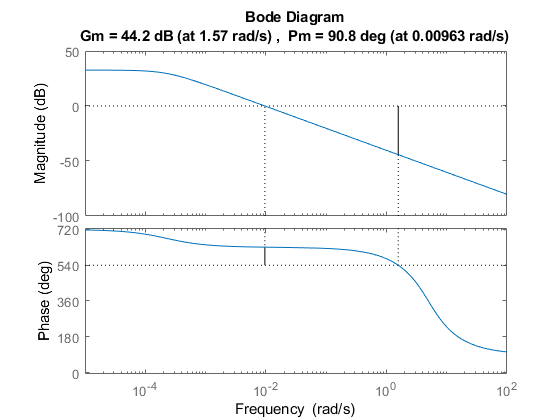

margin(G_plant_delay)

kp = freqresp(G_plant_delay, 0);
fejl = 1 / (1 + kp)

fejl = 0.0229

## Design regulator

H = 0.5;

G = G_plant_delay * H;

## Analyse af reguleret system

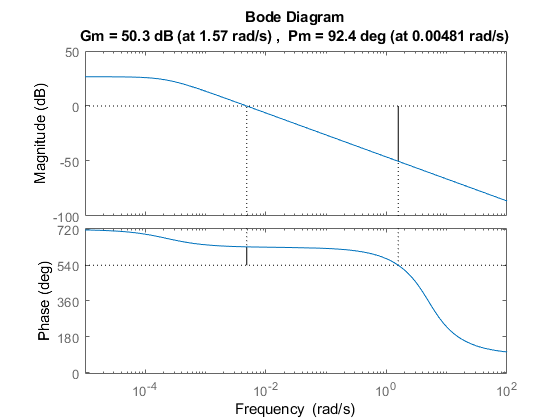

margin(G)

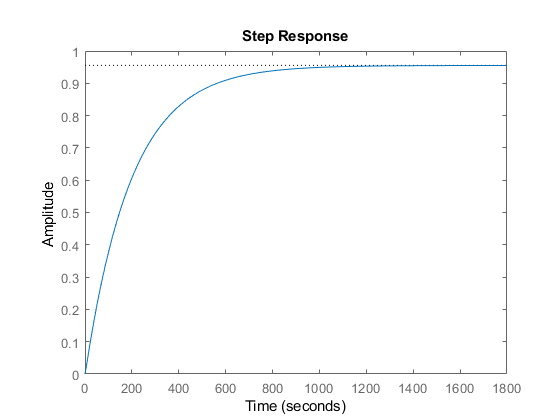

step(feedback(G, 1))